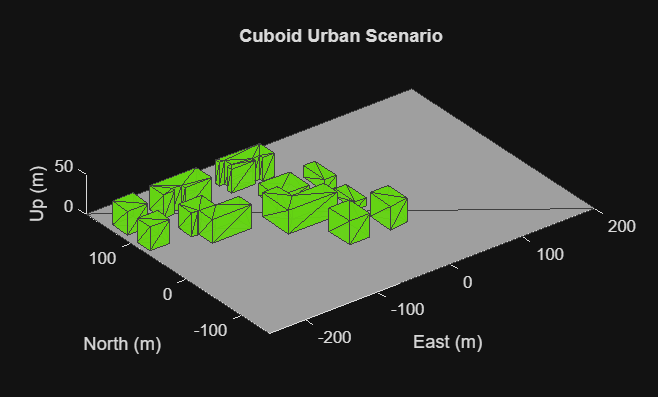

 scene = uavScenario(UpdateRate=2,ReferenceLocation=[75 -46 0]);

% Add a ground plane.
color.Gray = 0.651*ones(1,3);
color.Green = [0.3922 0.8314 0.0745];
color.Red = [1 0 0];
addMesh(scene,"polygon",{[-250 -150; 200 -150; 200 180; -250 180],[-4 0]},color.Gray)

% Load building polygons.
load("C:\Users\Lenovo\MATLAB Drive\Multi-UAV-Urban-Air-Mobility\Multi-UAV-Urban-Air-Mobility\Multi-UAV-Urban-Air-Mobility\data\buildingData.mat");

% Add sets of polygons as extruded meshes with varying heights from 10-30.
addMesh(scene,"polygon",{buildingData{1}(1:4,:),[0 30]},color.Green)
addMesh(scene,"polygon",{buildingData{2}(2:5,:),[0 30]},color.Green)
addMesh(scene,"polygon",{buildingData{3}(2:10,:),[0 30]},color.Green)
addMesh(scene,"polygon",{buildingData{4}(2:9,:),[0 30]},color.Green)
addMesh(scene,"polygon",{buildingData{5}(1:end-1,:),[0 30]},color.Green)
addMesh(scene,"polygon",{buildingData{6}(1:end-1,:),[0 15]},color.Green)
addMesh(scene,"polygon",{buildingData{7}(1:end-1,:),[0 30]},color.Green)
addMesh(scene,"polygon",{buildingData{8}(2:end-1,:),[0 10]},color.Green)
addMesh(scene,"polygon",{buildingData{9}(1:end-1,:),[0 15]},color.Green)
addMesh(scene,"polygon",{buildingData{10}(1:end-1,:),[0 30]},color.Green)
addMesh(scene,"polygon",{buildingData{11}(1:end-2,:),[0 30]},color.Green)

% Show the scenario.
show3D(scene);
xlim([-250 200])
ylim([-150 180])
zlim([0 50])
title('Cuboid Urban Scenario');